% i5h = randperm(500)
% save("id.mat","idx","c") % ,"q"
% save("/MATLAB Drive/id.mat","g","-append") % i5h
m = '/MATLAB Drive/';%O/B o/
% ad = [m "Sim/O/B o/id.mat"];
ad = [m 'id.mat']; % ''
load(ad)%O/B o/
whos("-file",ad) % 1, 4, 5 & 2

  Name      Size                Bytes  Class     Attributes

  c         2x5                 70120  cell                
  cg        2x5              26406800  cell                
  g         2x1               5281360  cell                
  g5        2x1               8193560  cell                
  i5h       1x500                4000  double              
  idx       1x5                    40  double              



% for r = 1:2
%     for co = 1:5
%         c{r,co}.PixelX(3:end) = c{r, ...
% co}.PixelX(2);
%     end
% end
% c

cc = cell(2,2); tr = 400; ci = [1:5 1:5];
for r = 1:2
    cc{r,2} = [c{r,idx(1)};c{r,idx(ci( ...
        2))}; c{r,idx(ci(3))}; ...
        c{r,idx(ci(4))}; c{r,idx(ci(5))}];
    t = cc{r,2}; cc{r,1} = t(i5h(1:tr),:);
    cc{r,2} = t(i5h(tr+1:end),:);
end
cc

cc = 2x2 cell array
    {400x6 table}    {100x6 table}
    {400x6 table}    {100x6 table}



co = 1; cc{1,co}.Ylatitude(:) = cc{1,...
    co}.Ylatitude(:)*10;
cc{2,co}.Ylongitude(:) = cc{2,...
    co}.Ylongitude(:)*10;

# Latitude gpr:

% rng('default')
g = cell(2,1); tic
for r = 1:2
    g{r,1} = fitrgp(cc{r,1}, ... % gprMdll
    cc{r,1}.Properties.VariableNames{end},...
    'Sigma',.002);
end
toc

Elapsed time is 0.973337 seconds.


g

g = 2x1 cell array
    {1x1 RegressionGP}
    {1x1 RegressionGP}



addpath('/MATLAB Drive/Sim');
tr = 400; co = 2;
% tr = 100; co = 1;
d1km = zeros(500-tr, 1); d2km = d1km;
% g5 = g;
% save("/MATLAB Drive/id.mat","g5","-append")
p = zeros(500-tr,2);
for r = 1:2
    t = cc{r,co};
    p(:,r) = predict(g{r,1},t(:, 1: ...
        end-1).Variables);
end

## d

fi = 1; f = 1/10;
for i = 1:500-tr
    [d1km(i), d2km(i)] = lldistkm(...
        [cc{1,co}.Ylatitude(i) ...
        cc{2,co}.Ylongitude(i)]*fi, ...
    [p(i,1) p(i,2)]*f);
end
% d1km(1:5,:)
m = zeros(2, 1);
[m(1),i] = min(d1km(:)*1000);
[m(2),I] = max(d1km(:)*1000);

table([m(1),i]', [m(2),I]','VariableNames',{...
    'Min','Max'},'RowNames',{'Distance(m)';...

ans = 2x2 table
                     Min       Max  
                   _______    ______

    Distance(m)    0.13264    9.5407
    Position            17        71


    'Position'})

% table([m(1),i; m(2),I]','VariableNames',{'Min',
% 'Max'})
fprintf('Nr. of distances < 10 m: %d',sum(...
    d1km(:)*1000<10))

Nr. of distances < 10 m: 100


% ypred = resubPredict(g{r,1})
% i = I; [cc{1,2}.Ylatitude(i) ...
%         cc{2,2}.Ylongitude(i); p(i,1) p(i,2)]
% 
% t = cc{1,2};tt = cc{2,2};t(I, :)
% tt(I,:)

% sympref('FloatingPointOutput',true);
% latex(sym([(1:5)' m']))

% [c{1,idx(5)}.Ylatitude(1:5) ...
%     c{2,idx(5)}.Ylongitude(1:5)]
% 
% k = zeros(5,2);
% for co = 1:5
%     k(co, :) = [c{1,co}.Ylatitude(5) c{2, ...
%         co}.Ylongitude(5)];
% end
% k
% 
% ci = [5 1:5-1]
% for co = 1:5
%     [cc{1,co}.Ylatitude(1:100:end) ...
%     cc{2,co}.Ylongitude(1:100:end);c{1, ...
%         idx(ci(co))}.Ylatitude(5) ...
%     c{2,idx(ci(co))}.Ylongitude(5); ...
%     p(5,1,co) p(5, 2,co)]
% end

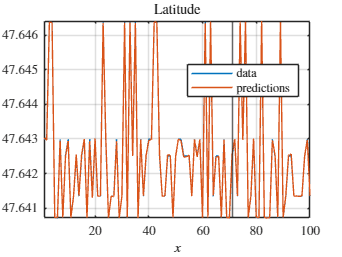

figure()
% plot(sort(cc{1,co}.Ylatitude(:)))
plot(cc{1,2}.Ylatitude(:))
xlabel('$x$','interpreter','latex'); axis tight
axe()
% hold on; plot(sort(p(:,1))*f); % ypred
hold on; plot(p(:,1)*f); % ypred
hold off; grid on; xline(I)

legend({'data','predictions'}, ...
    'Location','Best','interpreter','latex')
title('Latitude','interpreter','latex')

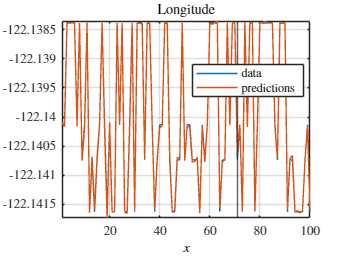


figure()
plot(cc{2,2}.Ylongitude(:));
% plot(sort(cc{2,co}.Ylongitude(:)));
axis tight; xlabel('$x$','interpreter','latex')
axe()
hold on
% plot(sort(p(:,2))*f)
plot(p(:,2)*f)
hold off; grid on; xline(I)
legend({'data','predictions'}, ...
    'Location','Best','interpreter','latex')
title('Longitude','interpreter','latex')

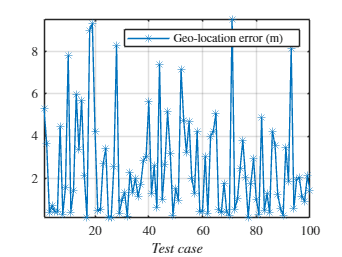

figure; plot(d1km*1000,'-*');
axis tight
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
    'interpreter','latex')
% ylabel('Geo-location error (in meters)', ...
%     'interpreter','latex')
axe()
% print(fig,'DistG','-djpeg')
grid on %title('distance(Km)')

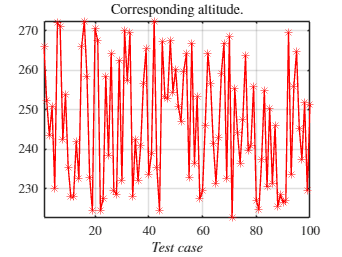


figure; plot(cc{1,2}.Altitude(:),'r-*');
xlabel('$Test$ $case$','interpreter','latex');axe()
% ylabel('')
grid on; title('Corresponding altitude.', ...
    'interpreter','latex'); axis tight

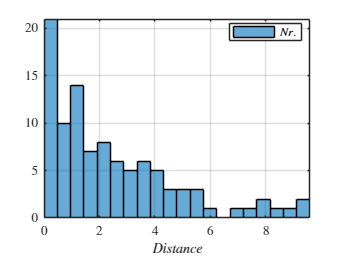

% print(fig,'Ca','-djpeg')

fig = figure; histogram(d1km*1000,20)
xlabel('$Distance$','interpreter','latex'); axe()
grid on
legend({'$Nr.$'}, 'Location', 'Best', ...
    'interpreter', 'latex');
% title(['$SNR = $',num2str(so)], ...
%     'interpreter','latex')
axis tight

% print(fig,'Hdist','-djpeg')

# Other tested GPR's for reference ...

# Longitude gpr:

% rng('default')
tic
for r = 2
    g{r,1} = fitrgp(cc{r,1}, ... % gprMdll
    cc{r,1}.Properties.VariableNames{end}, ...
    'Sigma',.002);
    % cc{r,1}.Properties.VariableNames{end}, ...
    % 'Sigma',.002);
end
toc

# Gpr:

% rng('default')
g = cell(2,1); tic
for r = 1:2
    g{r,1} = fitrgp(cc{r,1}, ... % gprMdll
    cc{r,1}.Properties.VariableNames{end}, ...
    'KernelFunction', 'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002);
end
toc
g

# Longitude gpr:

% rng('default')
g = cell(2,1); tic
for r = 1:2
    g{r,1} = fitrgp(cc{r,1}, ... % gprMdll
    cc{r,1}.Properties.VariableNames{end}, ...
    'KernelFunction', 'ardmatern52',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002);
end
toc
g

cc{1,co}

# gpr:

% rng('default')
% g = cell(2,1); tic
% for r = 1:2
%     t = cc{r,1};
%     % sigma0 = .002;%std(t(:,end).Variables);
%     sigma0 = std(t(:,end).Variables);
%     % sigmaF0 = std(t(:,end).Variables);
%     sigmaF0 = sigma0;
%     d = size(t,2)-1; sigmaM0 = 10*ones(d,1); 
%     g{r,1} = fitrgp(t, ... % gprMdll
%     t.Properties.VariableNames{end}, ...
%     'Basis','constant',...
%       'FitMethod','exact','PredictMethod', ...
%       'exact','KernelFunction',...
%       'ardsquaredexponential',...
% 'KernelParameters', ...
%       [sigmaM0;sigmaF0],'Sigma',sigma0,...
%       'Standardize',1);
% end
% toc
% g

# gpr:

% rng('default')
g = cell(2,1); tic
for r = 1:2
    t = cc{r,1};
    sigma0 = .002;%std(t(:,end).Variables);
    % sigmaF0 = std(t(:,end).Variables);
    % % sigmaF0 = sigma0;
    % d = size(t,2)-1; sigmaM0 = 10*ones(d,1); 
    g{r,1} = fitrgp(t, ... % gprMdll
    t.Properties.VariableNames{end}, ...
    'Basis','constant',...
      'FitMethod','exact','PredictMethod', ...
      'exact','KernelFunction',...
      'ardsquaredexponential','Sigma',sigma0);
end
toc
g

# gpr:

% rng('default')
g = cell(2,1); tic
for r = 1:2
    g{r,1} = fitrgp(cc{r,1}, ... % gprMdll
    cc{r,1}.Properties.VariableNames{end}, ...
    'KernelFunction', 'ardsquaredexponential',...
      'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName', ...
    'expected-improvement-plus'))
end
toc
g

# Longitude gpr:

% rng('default')
g = cell(2,1); tic
for r = 1:2
    g{r,1} = fitrgp(cc{r,1}, ... % gprMdll
    cc{r,1}.Properties.VariableNames{end}, ...
    'KernelFunction', 'squaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002);
end
toc
g

function axe()
    axes = gca;
    axes.XAxis.TickLabelInterpreter = 'latex';
    axes.YAxis.TickLabelInterpreter = 'latex';
end